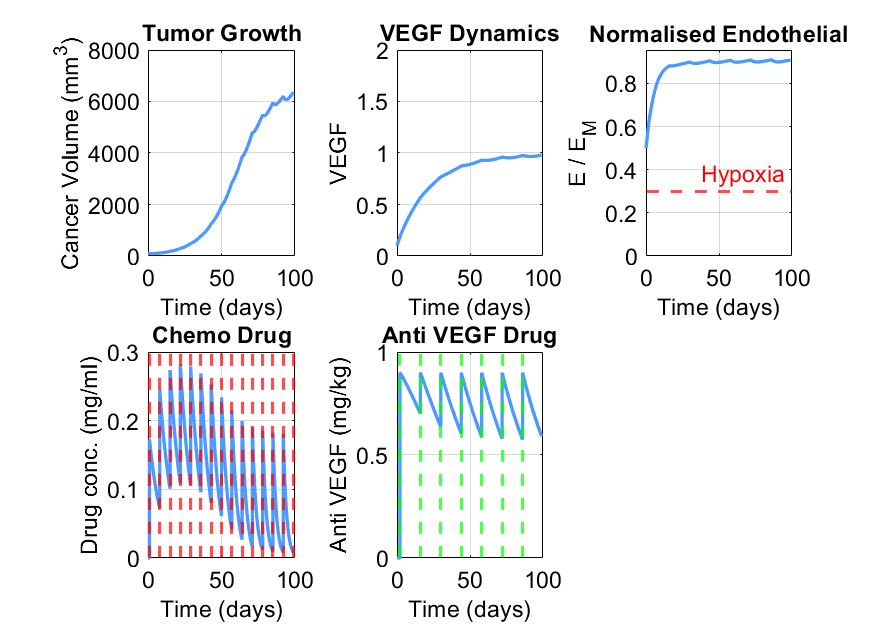

% Tumor model with gradual drug effect and capped drug concentrations (steady‑state plateau)
% ---------------------------------------------------------------------------
% Author: (your name / date)
% ---------------------------------------------------------------------------
% This script simulates cancer–endothelial–VEGF dynamics with chemotherapy and
% anti‑VEGF dosing. Drug concentrations are prevented from accumulating beyond
% physiological limits by capping them at a user‑defined maximum (D_max, A_max).
% ---------------------------------------------------------------------------

%% 1. Simulation time ---------------------------------------------------------
t0 = 0;           % start (days)
tf = 99;          % end   (days)

%% 2. Initial conditions  [ C ; D ;  E ;  V ;  A ] ---------------------------
%                               (mm³) (mg/ml) (—) (—)  (mg/kg)
x0 = [100.0497;   ... % Cancer cells
      0;          ... % Drug concentration (starts at 0)
      0.5;        ... % Endothelial cells
      0.1;        ... % VEGF
      0];             % Anti‑VEGF

%% 3. Model parameters --------------------------------------------------------
params = struct(...
    'd_c', 0.2030, ...       % Cancer natural death rate (1/day)
    'b', 0.22, ...           % Drug efficacy (increased for stronger effect)
    'lambda_ce', 0.3579, ... % Cancer proliferation (1/day)
    'd_d', 0.12, ...         % Chemo drug clearance (slower clearance)
    'b_k', 6e-5, ...         % Drug binding rate (/day)
    'c_M', 1e4, ...          % Cancer carrying capacity (mm³)
    'E_thresh', 0.3, ...     % Hypoxia threshold (E/E_M)
    'lambda_e', 0.3, ...     % Endothelial proliferation (1/day)
    'E_M', 1.0, ...          % Endothelial carrying capacity (—)
    'd_e', 0.02, ...         % Endothelial death (1/day)
    'd_v', 0.024, ...        % VEGF decay (1/day)
    'd_b', 0.008, ...        % Anti‑VEGF clearance (slower)
    'lambda_v0', 14.4, ...   % VEGF production rate when hypoxic (1/day)
    'k', 0.1, ...            % VEGF‑induced proliferation (1/day)
    'mu_Bk', 0.025, ...      % Anti‑VEGF binding clearance (increased)
    'V_M', 0.01, ...         % Michaelis‑Menten constant for VEGF (—)
    ... % Dosing
    'dose_amount', 0.173, ...        % Chemo dose (mg/ml)
    'dose_times', [1 8 15 22 29 36 43 50 57 64 71 78 85 92 99], ... % Chemo schedule (days)
    'anti_dose_amount', 1, ...   % Anti‑VEGF dose (mg/kg)
    'anti_dose_times', [2 16 30 44 58 72 86], ... % Anti‑VEGF schedule (days)
    ... % Max drug concentrations (plateau)
    'D_max', 2.5, ...        % Max chemo concentration (mg/ml)
    'A_max', 0.9 ...         % Max anti‑VEGF concentration (mg/kg)
);

% Pre‑compute list of all event times (for piece‑wise integration)
all_events = unique([params.dose_times, params.anti_dose_times]);

%% 4. Integration set‑up ------------------------------------------------------
options = odeset('Events', @(t,y) combinedEvents(t,y,params));
all_t = []; all_Y = [];

current_time = t0;
current_Y    = x0;
current_event_idx = 1;

%% 5. Piece‑wise integration between injection events ------------------------
while current_time < tf && current_event_idx <= numel(all_events)
    next_event = all_events(current_event_idx);
    t_span     = [current_time, next_event];

    % Integrate until the next event (dose)
    [T, Y, te] = ode15s(@(t,y) Model_with_injections(t,y,params), t_span, current_Y, options);

    all_t = [all_t; T];        %#ok<AGROW>
    all_Y = [all_Y; Y];        %#ok<AGROW>

    % Update state at the event time
    current_time = T(end);
    current_Y    = Y(end,:)';

    % Apply bolus doses and enforce plateau caps ---------------------------
    if ~isempty(te)
        if ismember(next_event, params.dose_times)
            current_Y(2) = min(current_Y(2) + params.dose_amount, params.D_max);
        end
        if ismember(next_event, params.anti_dose_times)
            current_Y(5) = min(current_Y(5) + params.anti_dose_amount, params.A_max);
        end
        current_event_idx = current_event_idx + 1;
    end
end

% Integrate the remainder of the time horizon (after last injection)
if current_time < tf
    [T, Y] = ode15s(@(t,y) Model_with_injections(t,y,params), [current_time tf], current_Y);
    all_t = [all_t; T];
    all_Y = [all_Y; Y];
end

T = all_t;  X = all_Y;

figure('Color','w','Position',[100 100 1000 720]);   % taller figure for vertical plots

% Common styling
fontName  = 'Arial';
fontSize  = 14;
lineWidth = 2;
lightBlue = [0.3 0.6 1];
black     = [0 0 0];

% Tumor growth
subplot(2,3,1);
plot(T, X(:,1), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)',          'FontName',fontName,'FontSize',fontSize,'Color',black);
ylabel('Cancer Volume (mm^3)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
title('Tumor Growth',          'FontName',fontName,'FontSize',fontSize,'FontWeight','bold','Color',black);
grid on; box on;
ylim([0 8000]); % Limit Y axis for better comparison

% VEGF dynamics
subplot(2,3,2);
plot(T, X(:,4), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
ylabel('VEGF',        'FontName',fontName,'FontSize',fontSize,'Color',black);
title('VEGF Dynamics','FontName',fontName,'FontSize',fontSize,'FontWeight','bold','Color',black);
grid on; box on;
ylim([0 2]); %Limit y for better comparison

% Normalised endothelial cells
subplot(2,3,3);
E_norm = X(:,3) ./ params.E_M;
plot(T, E_norm, 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
yline(params.E_thresh, '--r', 'Hypoxia', ...
    'LineWidth', lineWidth, 'FontName', fontName, 'FontSize', fontSize, 'Color', 'r');
xlabel('Time (days)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
ylabel('E / E_M',     'FontName',fontName,'FontSize',fontSize,'Color',black);
title('Normalised Endothelial','FontName',fontName,'FontSize',fontSize,'FontWeight','bold','Color',black);
ylim([min(0, params.E_thresh - 0.05), max(E_norm)*1.05]);
grid on; box on; hold off;

% Chemo Drug Concentration
subplot(2,3,4);
plot(T, X(:,2), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t, '--r', 'LineWidth', lineWidth), params.dose_times);
hold off;
xlabel('Time (days)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
ylabel('Drug conc. (mg/ml)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
title('Chemo Drug', 'FontName',fontName,'FontSize',fontSize,'FontWeight','bold','Color',black);
grid on; box on;

% Anti VEGF Drug Concentration
subplot(2,3,5);
plot(T, X(:,5), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t, '--g', 'LineWidth', lineWidth), params.anti_dose_times);
hold off;
xlabel('Time (days)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
ylabel('Anti VEGF (mg/kg)', 'FontName',fontName,'FontSize',fontSize,'Color',black);
title('Anti VEGF Drug', 'FontName',fontName,'FontSize',fontSize,'FontWeight','bold','Color',black);
grid on; box on;

% Apply Arial + black to everything else (ticks, axes, legends, etc.)
set(findall(gcf,'Type','axes'), 'FontName',fontName,'FontSize',fontSize,'XColor',black,'YColor',black);
set(findall(gcf,'Type','text'), 'FontName',fontName,'FontSize',fontSize,'Color',black);

% Save figure to Desktop (optional, remove if not needed)
desktopPath = fullfile(getenv('USERPROFILE'), 'Desktop'); % Windows path
if ~isfolder(desktopPath)
    desktopPath = fullfile(getenv('HOME'), 'Desktop'); % Mac/Linux fallback
end
filename = fullfile(desktopPath, 'tumor_model_plot.png');
saveas(gcf, filename);

disp(['Figure saved to: ', filename]);

Figure saved to: C:\Users\31628\Desktop\tumor_model_plot.png





%% 7. Local functions --------------------------------------------------------


function dYdt = Model_with_injections(~, Y, params)
    % Unpack state variables
    C = Y(1);  D = Y(2);  E = Y(3);  V = Y(4);  A = Y(5);

    % Pre-compute reusable terms
    E_frac = E / params.E_M;
    hypoxic = E_frac < params.E_thresh;

    % Baseline VEGF production to avoid VEGF going to zero
    basal_lambda_v = 0.05;

    % Tumor growth (logistic + endothelial support)
    dCdt = params.lambda_ce * E_frac * C * (1 - C/(params.c_M * (1 + E_frac))) ...
           - params.d_c * C - params.b * C * D;

    % Chemo drug dynamics
    dDdt = -params.d_d * D - params.b_k * C * D * E_frac;

    % Endothelial cells dynamics (with death induced by anti-VEGF)
    dEdt = params.lambda_e * (V/(V + params.V_M)) * E * (1 - E/params.E_M) ...
           - params.d_e * E + params.k * V * E * (1 - E/params.E_M) ...
           - params.mu_Bk * A * E;   % <-- New term: endothelial death due to anti-VEGF

    % VEGF dynamics
    dVdt = basal_lambda_v ...                      % baseline VEGF production
           + (hypoxic * params.lambda_v0) * C * (1 - E_frac) ... % hypoxia induced VEGF
           - params.k * V * E * (1 - E_frac) ...    % VEGF consumption
           - params.d_v * V ...                      % VEGF decay
           - params.mu_Bk * V * A;                   % clearance by anti-VEGF

    % Anti-VEGF drug dynamics
    dAdt = -params.d_b * A - params.mu_Bk * V * A;

    dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];
end

function [value, isterminal, direction] = combinedEvents(t, ~, params)
    value      = t - sort([params.dose_times, params.anti_dose_times]);
    isterminal = ones(size(value));
    direction  = ones(size(value));
end

